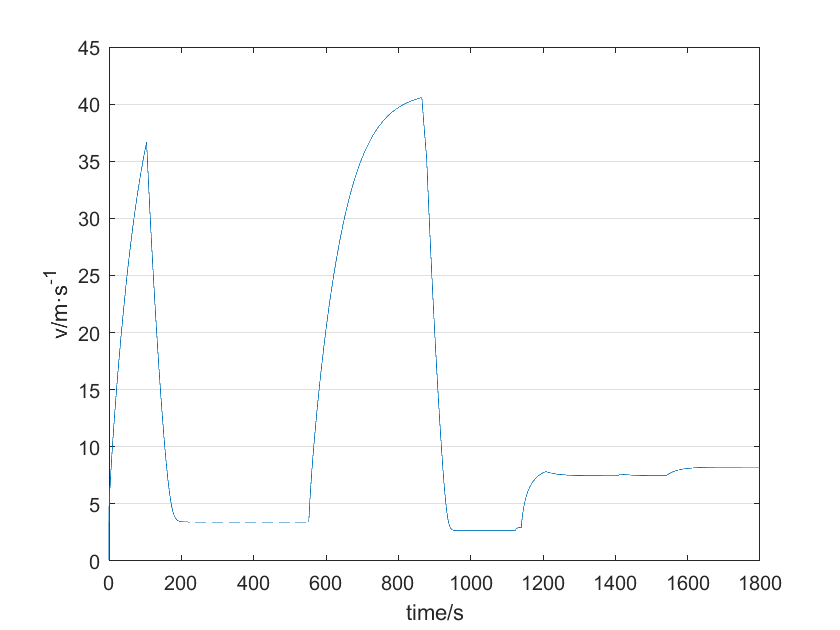

clear t1
t1.a=0; t1.b=0.25;   t1.c=1.05*treal;
v0 = 0.1;
td = 0;
clear theta v S Preal I;
Preal(1) = P0;
S(1) = 0.1;
close all
for t=t1.a:t1.b:t1.c    % s
    td=td+1;
    % 位置
    I(td)=1;
    for ii=1:size(L,2)
        if S(td)>=L(1,ii)
            I(td)=ii+1;
        end
    end
    % 坡度 t
    theta(td)=L(2,I(td));
    % 速度 t
    phy = 11;
    switch phy
        case 11
            if td==1
                syms un
                Fw(td)=0;
                v(td)=double(solve(m*un^2-(0.1*m-f*t)*un-Preal(td)*t==0,un>0));% fuhaojie
            else
                Fw(td)=1/2*r2*rho*Sw*v(td-1)^2;
                switch L(3,I(td))
                    case 0
                        v(td)=(((Preal(td) )/v(td-1)- Fw(td))/m - (r1*cos(theta(td))+sin(theta(td)))*g ) *t1.b + v(td-1);
                    case 1 % warning('急转弯')
                        Preal(td)=0.9*P0;
                        v(td)=(((Preal(td) )/v(td-1)- Fw(td))/m - (r1*cos(theta(td))+sin(theta(td)))*g ) *t1.b + v(td-1);
                end
            end
        case 1
            % syms un
            v(td)=max([1/20 - (5*((5531904*t^2)/9765625 + (149774208*t)/78125 + 2304/625)^(1/2))/192 - (49*t)/2500
                (5*((5531904*t^2)/9765625 + (149774208*t)/78125 + 2304/625)^(1/2))/192 - (49*t)/2500 + 1/20]);
            % v(td)=double(solve(m*un^2-(0.1*m-f*t)*un-Preal(td)*t==0,un>0));  %fuhaojie
            % v(td)=((Preal(td)/v0-f)*td+v0)/m;
        case 2
            v(td)=Preal(td)/f*(1-exp(-1-f^2/(m*Preal(td))*t));
        case 3
            syms un
            C = Preal(td)/f*log(Preal(td)/f);
            eqn = un+Preal(td)/f*log(abs(un-Preal(td)/f)) == -f/m*t+C;
            v(td) = double(vpasolve(eqn,un));
        otherwise warning('!')
    end
    % S t+1
    if td==1;
        S(td+1)=1/2*(v0+v(td))*t1.b;
    else S(td+1) = S(td)+v(td)*t1.b;
        if S(td+1)>=max(L(1,:))
            t1.end=t1.a+t1.b*(td-1);
            S(td+1)=[];
            break
        end
    end
    % P t+1
    Preal(td+1) = P0 * 1;
    %     congci=0;
    %     l.a = find(min(S(td))>=pm.P0{1}(1));
    %     if isempty(l.a)==0
    %         if t-l.a<=pm.P0{1}
    %             congci=1;
    %         end
    %     end
    %     l.b=find(min(S(td))>=pm.P0{1}(2));
    %     if isempty(l.b)==0
    %         if t-l.b<=pm.P0{2}
    %             congci=1;
    %         end
    %     end
    %     if congci==1
    %         Preal(td+1) = P0 * pm.P0{2};
    %     end
    %     pilao=0;
    %     if isempty(l.a)==0
    %         if t-l.a<=pm.P0{3}
    %             pilao=1;
    %         end
    %     end
    %     if isempty(l.b)==0
    %         if t-l.b<=pm.P0{3}
    %             pilao=1;
    %         end
    %     end
    %     if pilao==1
    %         Preal(td+1) = P0 * pm.P0{4};
    %     end
    %     if t>=5 || t<=6
    %         Preal(t)= P0 * pm.P0{2};
    %     elseif t>=29 || t<=30
    %         Preal(t)= P0 * pm.P0{2};
    %     end
    %     if t>6 ||t<=7+5
    %         Preal(t)= P0 * pm.P0{4};
    %     elseif t>30 || t<=30+5
    %         Preal(t)= P0 * pm.P0{2}
    %     end
end

te=[t1.a:t1.b:t1.end];
figure;plot(te,v);hold on
xlabel('time/s');ylabel('v/m·s^{-1}');set(gca,'ygrid','on') ;hold off

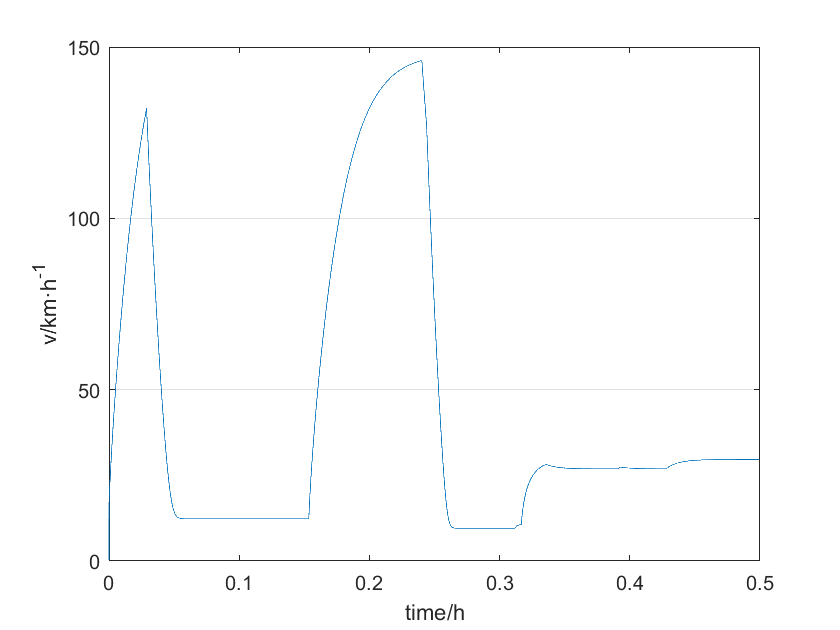


figure;plot(te/3600,v*((1/1000)/(1/3600)));hold on
xlabel('time/h');ylabel('v/km·h^{-1}');set(gca,'ygrid','on') ;hold off

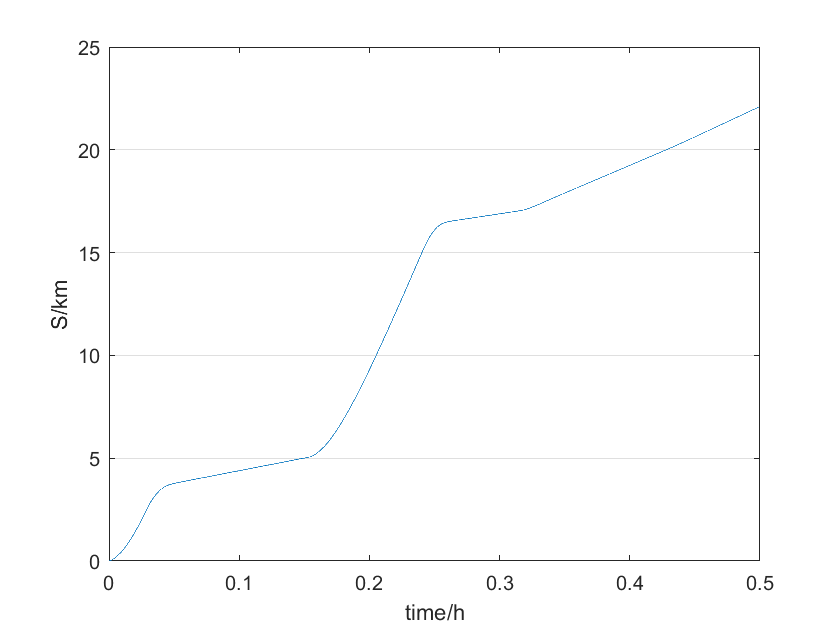


figure;plot(te/3600,S(1:size(te,2))/1000);hold on
xlabel('time/h');ylabel('S/km');set(gca,'ygrid','on') ;hold off

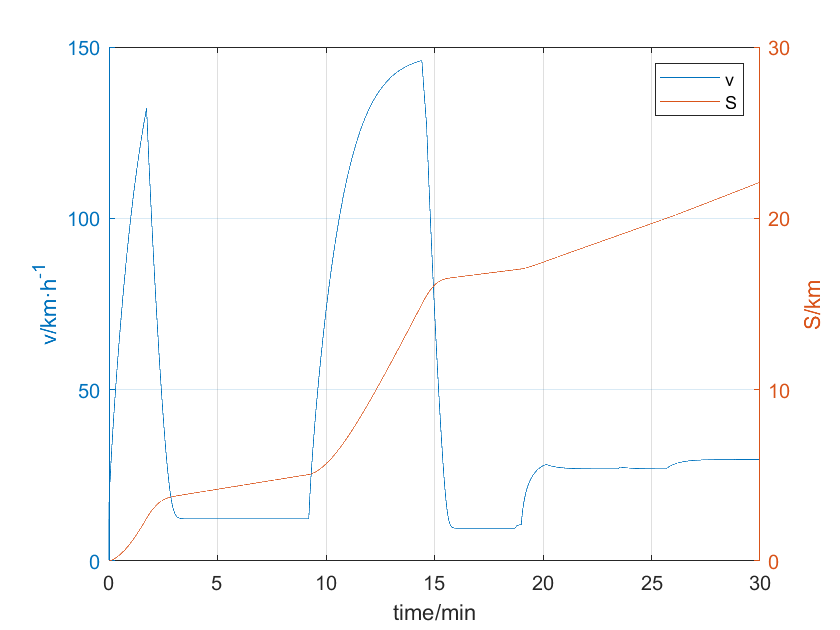


figure;
[Y,H1,H2]=plotyy(te/60,v*((1/1000)/(1/3600)),te/60,S/1000);hold on
legend('v','S')
xlabel('time/min');
set(get(Y(1),'ylabel'),'string', 'v/km·h^{-1}');%,'fontsize',16
set(get(Y(2),'ylabel'),'string', 'S/km');
grid on;
pc=(t1.end-treal)/treal;

hold on